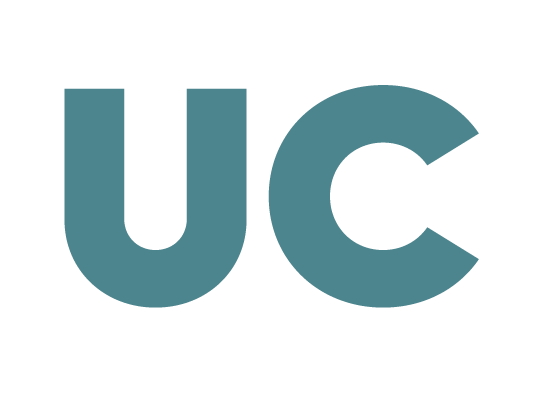

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 7: Espacio Euclídeo**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Operar con productos escalares en MATLAB

- Obtener el complemento ortogonal de un subespacio dado

- Calcular bases ortogonales (y ortonormales)

## **1 Producto escalar, norma y ángulo**

### 1.1 Producto escalar

En MATLAB, el producto escalar de dos vectores en $\mathbb{R}^n$ se obtiene multiplicando matricialmente un vector en fila por el otro vector en columna. 

Por ejemplo, en $\mathbb{R}^3$, el producto escalar de los vectores $\vec{u}=(4,0,3)$ y $\vec{v}=(1,-2,3)$ se obtendría así:

u = [4 0 3]' ;  % vector u
v = [1 -2 3]';  % vector v
u'*v

Otra opción muy conveniente es usar la función *dot* de MATLAB. En este caso no hay problema en que pasemos los vectores en formato fila o columna, *dot* devolverá su producto escalar.

- `dot(u,v):` producto escalar de dos vectores  

dot(u, v)  % producto escalar 

### 1.2 Norma

La norma de un vector $\|\vec{u} \parallel =\sqrt{\vec{u} \cdot \vec{u} }$ se puede calcular directamente en MATLAB con la función *norm.*

- `norm`*: *devuelve norma de un vector considerando el producto escalar

norm(u)          % norma del vector u 
sqrt(dot(u, u))  % comprobamos que obtenemos el mismo resultado

Por tanto, normalizar el vector$\vec{u}$ sería tan fácil como:

u_norm = u/norm(u)  % vector u normalizado
norm(u_norm)        % efectivamente, la norma del vector normalizado es 1

### **1.3 Distancia y ángulo entre dos vectores**

La distancia entre dos vectores cualesquiera de un espacio vectorial euclídeo $\vec{u}$y $\vec{v}$, es la norma del vector diferencia entre ambos. Por tanto, la distancia entre dos vectore se calcula en MATLAB de la siguiente forma:

v_diff = u-v             % vector diferencia u-v 
distancia = norm(v_diff) % norma del vector diferencia

Sabemos que el cálculo del producto escalar entre dos vectores cualesquiera de un espacio vectorial euclídeo  $\vec{u}$y $\vec{v}$, involucra el coseno del ángulo que forman de la siguiente forma: $$\vec{u} \cdot \vec{v} = \|\vec{u} \| \|\vec{v} \| \cos(\alpha)$, con $0 \leq \alpha \leq \pi$ $. Por tanto, el $$\alpha = arccos \frac{\vec{u} \cdot \vec{v}}{\parallel \vec{u} \parallel \parallel \vec{v} \parallel}  $$. En MATLAB el ángulo (en grados) se obtendría con la función `acosd`, que es la función arcoseno en grados degree):

alpha = acosd( dot(u,v) / (norm(u)*norm(v)) )

## **2 Cálculo de una base del subespacio complemento ortogonal**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, $S = \lbrace (\alpha, \alpha, \beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$. Para encontrar el complemento ortogonal (o simplemente ortogonal) de $S$, $S^
\perp$, tendremos que buscar todos los vectores ortogonales a $S$. Partiremos, para ello, de una base de $S$:

baseS = [1 1 0 0; 0 0 1 1]'  % base de S

$S^\perp$ estará formado por los vectores $(x,y,z,t)$ que satisfagan las siguientes ecuaciones:


$$(1,1,0,0) \cdot (x,y,z,t)=0 \\ (0,0,1,1) \cdot (x,y,z,t)=0$$


Los productos escalares anteriores, igualados a cero, se expresan como la siguiente ecuación matricial:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 0 & 0\\
0 & 0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z\\
t
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Por tanto, para hallar una base de $S^\perp$ bastaría con resolver el sistema homogéneo que tiene como matriz de coeficientes los vectores de la base de $S$ colocados por filas:

baseS_ortog = null(baseS', 'r')  % base de S_ortog

Como vemos, la base de $S^\perp$ está compuesta por dos vectores, por lo que $dim(S^\perp)=2$. Esto era de esperar, puesto que ya vimos que $dim(S)=2$, y sabemos que, por ser subespacios complementario  $dim(S)+dim(S^\perp)=4$. 

Efectivamente:

rank([baseS baseS_ortog])  % la unión de las bases de S y S_ortog forman base del espacio total R4

Podemos comprobar fácilmente que $S$ y $S^\perp$ son en efecto ortogonales viendo que el producto escalar de los vectores de sus bases (las combinaciones de todos) es $0$:

% Comprobación ORTOGONALIDAD
dot(baseS(:,1), baseS_ortog(:,1))
dot(baseS(:,1), baseS_ortog(:,2))
dot(baseS(:,2), baseS_ortog(:,1))
dot(baseS(:,2), baseS_ortog(:,2))

También se pueden hacer las cuatro comprobaciones de una vez ejecutando:

baseS'*baseS_ortog

## **3. Cálculo de una base ortonormal de un subespacio**

Una base ortogonal de un subespacio es aquella formada por un conjunto de vectores ortogonales entre sí. Al igual que existen infinitas bases de un subespacio, también existen infinitas bases ortogonales de un subespacio. 

Para obtener una base ortogonal en MATLAB tenemos dos opciones que veremos a continación: el uso de la función `null` y el de la función `orth.`

### 3.1 Función orth: Ortonormalización de un conjunto de vectores

En clase hemos visto el algoritmo de Gram-Schmidt para ortogonalizar una base. MATLAB permite ortogonalizar una base mediante el uso de la función *orth*

- `orth`(A): esta funcion ortonormaliza los vectores columna de la matriz A. Además, en caso de que A tenga vectores columna l.d. devolverá una matriz con una base en sus columnas (tantas columnas como la dimensión del espacio columna de A). Es importante tener en cuenta que la base ortonormal devuelta por orth no es la misma que obtendríamos por Gram-Schmidt, ya que implementa un procedimiento de ortonormalización diferente.

**Ejemplo**. Dado el siguiente subespacio,$$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$, de $\mathbb{R}^3$, vamos a obtener una base ortonormal de S utilizando *orth*.

Para empezar necesitamos una base cualquiera de S, para hallarla pasamos de implícitas a paramétricas resolviendo el sistema.

coefS=[ 2 -1 3];
baseS = null(coefS,"rational") % vectores de la base de S en columnas


$$$  \left(x, y, z\right)=\left(\alpha/2 - \frac{3}{2}\beta, \alpha, \beta \right)=\alpha (\frac{1}{2},1,0)+ \beta(-\frac{3}{2},0,1)$
$$
   

Ya tenemos la base (no ortogonal) de S. Ahora utilizaremos la función *orth* para ortonormalizar la base.

base_ort=orth(baseS)

Comprobamos que hemos obtenido una base ortonormal

dot(base_ort(:,1),base_ort(:,2))
[norm(base_ort(:,1))  norm(base_ort(:,2)) ]

Comprobamos además que los vectores de la base de S cumplen las ecuaciones implícitas de S

coefS*base_ort(:,1) % b1 verifica la ecuacion implícita Ax=0
coefS*base_ort(:,2)% b2 verifica la ecuacion implícita Ax=0

### 3.2 Función null: permite hallar una base ortonormal a partir de ecuaciones implícitas

- null(A): la función *null* de A devuelve una base de un sistema homogéneo cuya matriz de coeficientes es A. Si no ponemos el argumento "r" o "rational"  nos devolverá una base ortonormal.

- null(A,"rational"): Si  ponemos el argumento "r" o "rational"  nos devolverá una base no ortogonal con vectores con números enteros o racionales.

Continuamos con el ejemplo anterior, subespacio $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$de $\mathbb{R}^3$

Si indicamos el argumento 'rational' nos devolverá una base con números racionales, pero que no tiene porque ser ortogonal.

coefImpS = [2 -1 3];  % coefs. eqs. implícitas S
baseS = null(coefImpS, 'rational')  % base de S (no ortogonal)
dot(baseS(:,1), baseS(:,2))  % vemos que NO es ortogonal -> no es ortonormal

Si no añadimos el argumento 'rational', la función null devuelve una base ortonormal.

baseortonS = null(coefImpS)  % base ORTONORMAL de S
% comprobación de ortonorgonalidad
dot(baseortonS(:,1), baseortonS(:,2))
% Comprobación ORTONORMALIDAD 
[ norm(baseortonS(:,1)) norm(baseortonS(:,2)) ]

`Nota``:` fíjate que las base ortogonales obtenidas para el subespaico $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$ por las funciones orth y null son diferentes.